# load image

%[fname, dname] = uigetfile('M:\Bergles Lab Data\Projects\In vivo imaging\*.tif','Multiselect','on');
[fname, dname] = uigetfile('M:\Bergles Lab Data\Papers\P2ry1\*.czi');

[~,~,ext] = fileparts([dname, fname]);

%%tif performance 
if strcmp(ext,'.tif') 
    tic;
    X = loadTif([dname fname],16);
    toc;
elseif strcmp(ext,'.czi')
    tic;
    X = bfLoadTif([dname fname]);
    X = imrotate(X,180);
    toc;
else
    disp('Invalid image format.')
end

Unknown IlluminationType value 'Fluorescence' will be stored as "Other"
Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ...........................................................

Elapsed time is 226.512606 seconds.


## get 10th percentiles

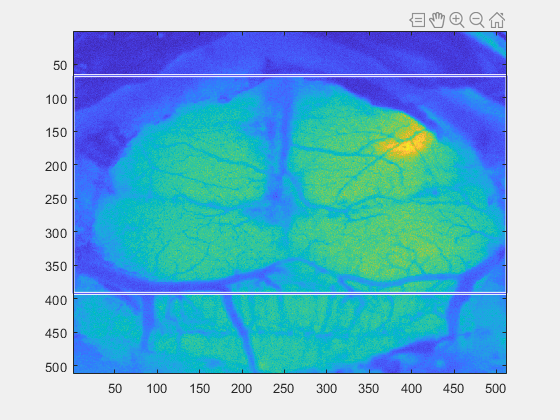

%cut down image first, then do normalization
figure; 
imagesc(X(:,:,1));
caxis([min(min(X(:,:,1))) max(max(X(:,:,1)))]);
recth = imrect(gca,[0 0 512 325]);
fcn = makeConstrainToRectFcn('imrect',get(gca,'XLim'),get(gca,'YLim'));
setPositionConstraintFcn(recth,fcn);
setResizable(recth,0);
wait(recth);

[s] = round(recth.getPosition); x = s(1); y = s(2); w=s(3); h=s(4);
Y = zeros(h,w,size(X,3));
Y = X(y:y+h-1,x:x+w-1,:);

clear X;
[dFoF, Fo, Y] = normalizeImg(Y, 10, 1);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 6612.254532 

Bleach correction finished. Subtracting baseline...


[m,n,t] = size(Y);

## Set ROI masks and generate signals

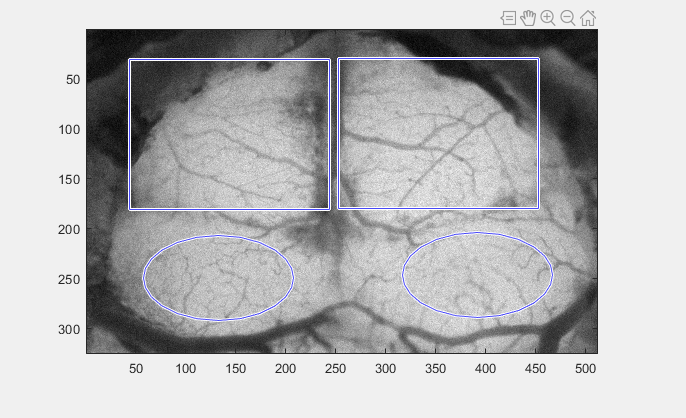

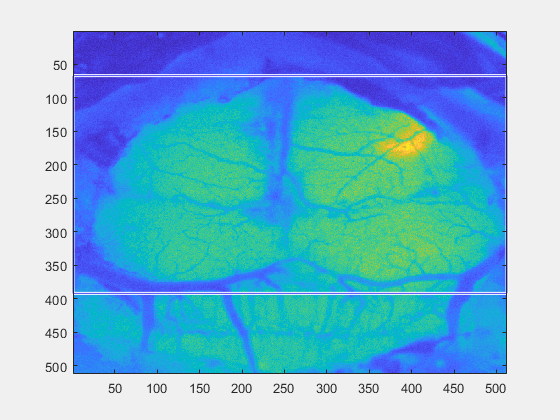

[LICmask, RICmask, LSCmask, RSCmask] = getIC_SCmasks(Y);

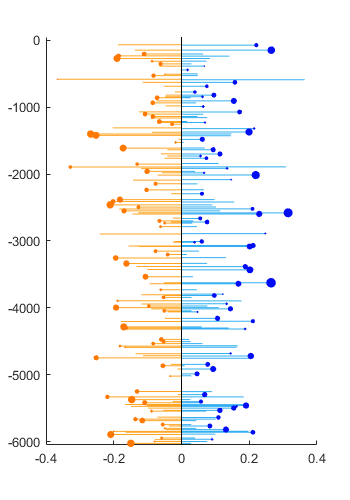

h1 =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1.8000 1.2000]
       Units: 'inches'

  Show all properties


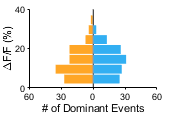

Rdom = 127

tempPkData = 	1.0e+04 *

    0.0205    0.0000    0.0205    0.0000    0.0000    0.0002    0.0001
    0.0232    0.0000    0.0235    0.0000    0.0000    0.0001    0.0001
    0.0271    0.0000    0.0271    0.0000    0.0000    0.0002    0.0001
    0.0312    0.0000    0.0311    0.0000    0.0000    0.0001    0.0001
    0.0352    0.0000    0.0352    0.0000    0.0000    0.0002    0.0001
    0.0506    0.0000    0.0502    0.0000    0.0000    0.0001    0.0001
    0.0527    0.0000    0.0527    0.0000    0.0000    0.0002    0.0001
    0.0582    0.0000    0.0589    0.0000    0.0000    0.0001    0.0001
    0.0858    0.0000    0.0858    0.0000    0.0000    0.0002    0.0001
    0.0934    0.0000    0.0934    0.0000    0.0000    0.0002    0.0001


LIC: 181 peaks total, 111 corresponding RIC peaks.
RIC: 177 peaks total, 111 corresponding LIC peaks.
Mean RIC amplitude: 0.11126
Mean LIC amplitude: 0.11075
M:\Projects and Analysis\Papers\P2ry1\Figure 5 - In vivo drug infusion\Data\Sham IP\Experiment-376\\ICinfo16_dFoF


LICsignal = getMeanFromMask(dFoF, LICmask);
RICsignal = getMeanFromMask(dFoF, RICmask);
ctxsignal = [getMeanFromMask(dFoF,LSCmask) + getMeanFromMask(dFoF,RSCmask)]/2;

[stats, pkData] = P2ry1_findICpeaksdFoF(double([LICsignal RICsignal ctxsignal]),[dname],'dFoF',1);


%make folders and analyzes IC activity
%foldername = regexp(fname,'Experiment-\d*','match');
%foldername = foldername{1};
%mkdir(dname,foldername);

%analyze SCactivity
[SCactivity, bin, events] = getSCactivity_new(dFoF,LSCmask);

ans =      1    21


[RSCactivity, Rbin, Revents] = getSCactivity_new(dFoF,RSCmask);

ans =      1    37


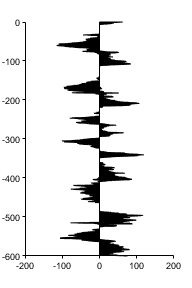


plotSCactivity(bin,Rbin);

SCactivity = struct('LSCactivity',SCactivity,'Lbin',bin,'Levents',events,'RSCactivity',RSCactivity,'Rbin',Rbin,'Revents',Revents);

savename = regexp(fname,'Experiment-\d*','match');
savename = savename{1};
save([dname savename '_SCactivity.mat'],'SCactivity','-v7.3');
save([dname savename '_masks.mat'],'s','LICmask', 'RICmask','LSCmask', 'RSCmask','-v7.3');


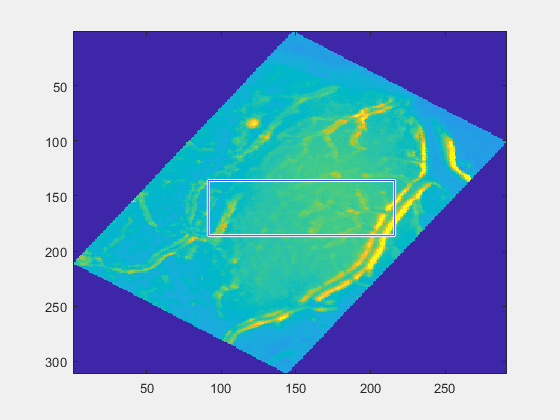

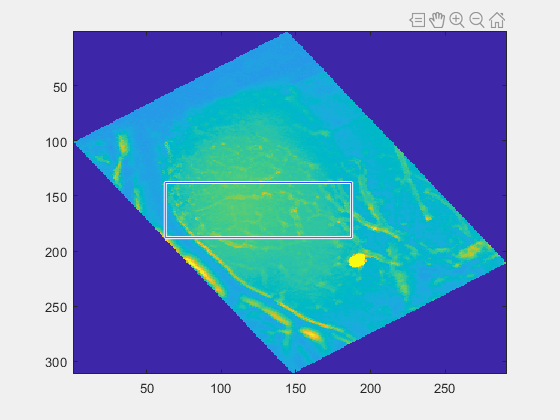

IConly = dFoF(end-174:end,:,:);

[LICmov, RICmov] = ROIselection(IConly);

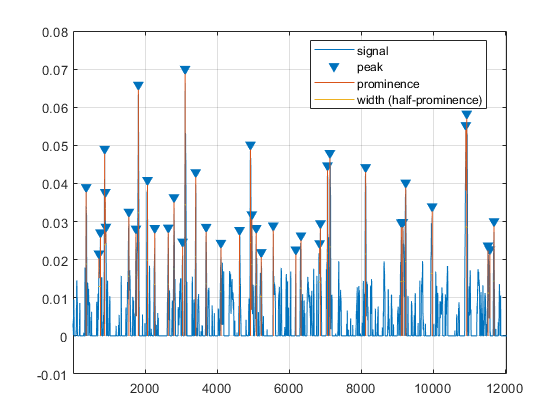

meanLIC = squeeze(mean(LICmov,1));
percentLIC = prctile(meanLIC,30,2);
meanRIC = squeeze(mean(RICmov,1));
percentRIC = prctile(meanRIC,30,2);

% %%remove background transients from signal
top = IConly(5:20,10:500,:); %picks area at top of image, middle to account for registration
top = squeeze(mean(mean(top),2));
mid = IConly(60:80,10:500,:);
mid = squeeze(mean(mean(mid),2));
diff = top - mid;
diff(diff < -0) = 0;
[pks,locs,w]=findpeaks(double(diff),'MinPeakHeight',0.02,'WidthReference','halfprom','MinPeakWidth',7,'Annotate','extents');
figure;
findpeaks(double(diff),'MinPeakHeight',0.02,'WidthReference','halfprom','MinPeakWidth',7,'Annotate','extents');

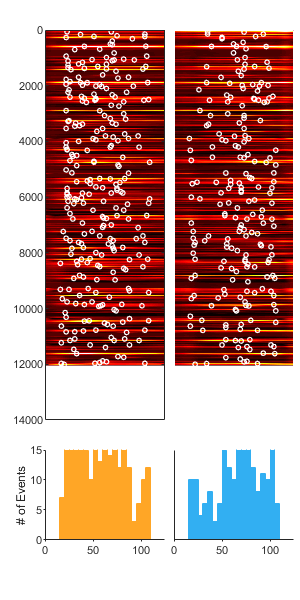

  0×1 empty cell array




flash = zeros(size(top));
for i=1:size(w,1)
    ww = floor(w(i));
    wloc = locs(i);
    left = wloc-ww-2;
    right = wloc+ww+2;
    if left < 1
        left = 1;
    end
    if right > t
        right = t;
    end
    flash(left:right) = 1;
end

[m,n] = size(meanLIC(:,find(flash)));
percentLIC = repmat(percentLIC,1,n);
percentLIC = imnoise(percentLIC,'gaussian',0,.0001);
percentLIC = imgaussfilt(percentLIC);
meanLIC(:,find(flash)) = percentLIC;
[m,n] = size(meanRIC(:,find(flash)));
percentRIC = repmat(percentRIC,1,n);
percentRIC = imnoise(percentRIC,'gaussian',0,.0001);
percentRIC = imgaussfilt(percentRIC);
meanRIC(:,find(flash)) = percentRIC;
% 
smLIC = double(imgaussfilt(meanLIC,3));
smRIC = double(imgaussfilt(meanRIC,3));

%LIC & RIC
[peaksBinaryL] = getPeaks_dFoF(smLIC,0,0.02);
[peaksBinaryR] = getPeaks_dFoF(smRIC,1,0.02);
  
[peakStat, eventStats] = P2ry1_peakStats_dFoF(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
plotTimeSeries_dFoF(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);

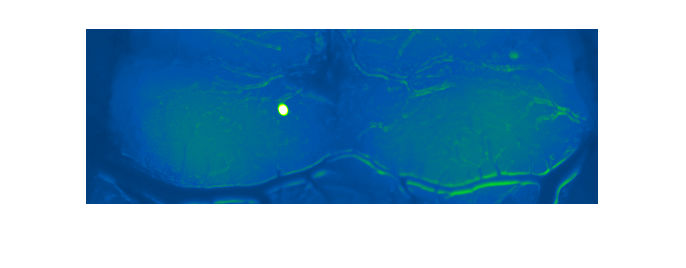

%%
savefile = 'ICDetailAnalysis.mat';
save([dname '\' savefile],'smLIC','smRIC','peaksBinaryR','peaksBinaryL'); 

temp = Y(end-174:end,:,:);
meantemp = Fo(end-174:end,:);
temp = mean(temp-meantemp,3);
figure; imshow(temp);
colormap gfb;
caxis([-100 800]);

writeTif(single(temp),[dname '\meantif.tif'],32);

% list = loadFileList('C:\Users\Public\*\*_stats.mat');
% group = struct([]);
% freqs = [];
% durs = []
% for i = 1:size(list,1)
%     load(list{i});
%     freqs(i,:) = [stats.baselineFreq/5 stats.mrsFreq/5];
%     durs(i,:) = [stats.baselineDur stats.mrsDur];
% end
% 
% compare2P(freqs(:,1),freqs(:,2),{'Control','MRS'},'SC waves per minute',[.75 1.25],[10 15]);
% ylim([0 5]);
% yticks([0:2.5:5]);
% export_fig('.\EPS Panels\SCfrequency.eps');
% compare2P(durs(:,1),durs(:,2),{'Control','MRS'},'Mean wave duration (s)',[.75 1.25],[10 15]);
% ylim([0 40]);
% yticks([0:20:40]);
% export_fig('.\EPS Panels\SC_duration.eps');